clear;
M = zeros(2, 4);
M(1, :) = [20 30 40 50];
M(2, :) = [8 23 28 34];
M

M =     20    30    40    50
     8    23    28    34


humid = M(1, :);
elec = M(2, :);
x = (M(1, :) - 35) / 5

x =     -3    -1     1     3



A = zeros(3, length(x))

A =      0     0     0     0
     0     0     0     0
     0     0     0     0


A(1, :) = x.^2

A =      9     1     1     9
     0     0     0     0
     0     0     0     0


A(2, :) = x

A =      9     1     1     9
    -3    -1     1     3
     0     0     0     0


A(3, :) =  A(3, :) + 1

A =      9     1     1     9
    -3    -1     1     3
     1     1     1     1


A = A'

A =      9    -3     1
     1    -1     1
     1     1     1
     9     3     1



y = elec'

y =      8
    23
    28
    34


%u = [A b]';
A_star = A' * A;
u_star = A' * y;

u = mldivide(A_star, u_star);
u = u'

u =    -0.5625    4.1500   26.0625


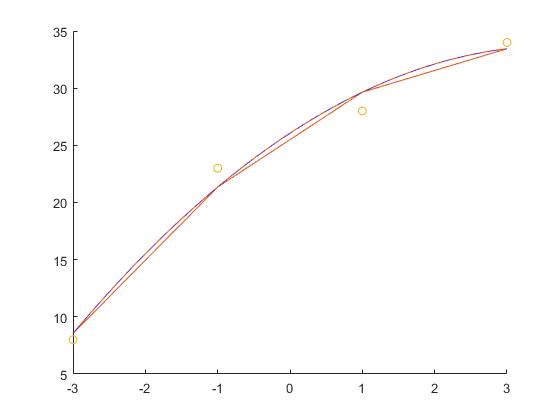


x_vec = linspace(-3, 3, 100);
quad_fit = u(1).*x_vec.^2 + u(2).*x_vec + u(3);
scatter(x, y);
hold on;
plot(x_vec, quad_fit, '--');